clc;
clear all;




% Example Inputs
Rot = eye(3); % Identity rotation matrix
TVect = [0; 0; 154]; 

d = 99.10;
theta = deg2rad([13.32, 46.68, 133.32, 166.68, 253.32, 286.68]);
BP =  [d *cos(theta); d *sin(theta); repmat(40, 1, 6)]

BP =    96.4341   67.9898  -67.9898  -96.4341  -28.4443   28.4443
   22.8316   72.0986   72.0986   22.8316  -94.9301  -94.9301
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000



% Define attachment points on the moving platform
b = 75.66;
phi = deg2rad([22.41, 37.59, 142.41, 157.59, 262.41, 277.59]);
% vector of where the end of limb goes with respect to platform
PP = b * [cos(phi); sin(phi); zeros(1, 6)]

PP =    69.9461   59.9527  -59.9527  -69.9461   -9.9934    9.9934
   28.8440   46.1531   46.1531   28.8440  -74.9971  -74.9971
         0         0         0         0         0         0


leg_length =   117.1911  117.1911  117.1911  117.1911  117.1911  117.1911


ans =    69.9461   59.9527  -59.9527  -69.9461   -9.9934    9.9934
   28.8440   46.1531   46.1531   28.8440  -74.9971  -74.9971
  154.0000  154.0000  154.0000  154.0000  154.0000  154.0000


new_angles =     0.1671    0.1759    0.1671    0.1759    0.1671    0.1759


leg1_base =    96.4341
   22.8316
   40.0000


leg1_platform =    69.9461
   28.8440
  154.0000


joint1 =    75.7264
   22.8316
   43.4920


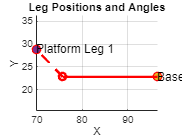


% Call the function to plot
plot_two_legs(Rot, TVect, BP, PP);

function plot_two_legs(Rot, TVect, BP, PP)
    % Calculate new angles
    new_angles = calcAngles(Rot, TVect, BP, PP)

    % Parameters
    s_leg = 119.0; % Length of operational length
    a_leg = 21.0; % Length of servo arm

    % Extract positions for two legs
    leg1_base = BP(:,1)
    leg1_platform = TVect + Rot*PP(:,1)

    % leg2_base = BP(:,2)
    % leg2_platform = TVect + Rot*PP(:,2)

    % Calculate the joint positions
    joint1 = calculate_joint_position(leg1_base, leg1_platform, s_leg, a_leg,pi-new_angles(1))

    % Plot the base, platform, and joint points
    figure;
    hold on
   
    % Plot leg 1 segments
    plot3([leg1_base(1), joint1(1)], [leg1_base(2), joint1(2)], [leg1_base(3), joint1(3)], 'r-o', 'LineWidth', 2);
    plot3([joint1(1), leg1_platform(1)], [joint1(2), leg1_platform(2)], [joint1(3), leg1_platform(3)], 'r--o', 'LineWidth', 2);

    
    % Plot base points
    scatter3(BP(1,1), BP(2,1), BP(3,1), 'filled');
    % Plot platform points
    scatter3(leg1_platform(1), leg1_platform(2), leg1_platform(3), 'filled');

    % Annotate the plot
    text(leg1_base(1), leg1_base(2), leg1_base(3), 'Base Leg 1');
    text(leg1_platform(1), leg1_platform(2), leg1_platform(3), 'Platform Leg 1');
  
    
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Leg Positions and Angles');
    grid on
    axis equal
    % legend('Leg 1 Segment 1', 'Leg 1 Segment 2', 'Leg 2 Segment 1', 'Leg 2 Segment 2');
    % 
    % hold off;
end

function joint = calculate_joint_position(base, platform, s_leg, a_leg, angle)
    % Calculate the position of the joint
    rod_vector = platform - base;
    rod_length = norm(rod_vector);
    rod_unit_vector = rod_vector / rod_length;

    joint_offset = a_leg * [cos(angle); 0; sin(angle)];
    joint = base + joint_offset;
end

function new_angles  = calcAngles(Rot, TVect, BP, PP)
    % Length of operational length
    s_leg = 119.0; % repmat(119.0, 1, 6);
    % Length of servo arm
    a_leg = 21.0; % repmat(21.0, 1, 6);

    % Definition of the platform home position
    % h= sqrt(s_leg.^2+ a_leg.^2 -(PP(1,:) - BP(1,:)).^2 - (PP(2,:) - BP(2,:)).^2) -PP(3,:);
    % home_pos= [0, 0, h(1)]'
    leg = zeros(3,6);
    leg_length = zeros(1,6);
    
    % Calculate effective rod length in Base System for all 6 rods
    for i=1:6
        % l_B Vector + home_pos 
        % TVect + Rot*PP(:,i)
        leg(:,i) = TVect+ Rot*PP(:,i) - BP(:,i);
        leg_length(i)= norm(leg(:,i));
    end
    
    
    % leg_length
    % leg + BP
    % Get coordinates of the points where the rod is attached to the platform 
    x_P= leg(1,:) + BP(1,:);
    y_P= leg(2,:) + BP(2,:);
    z_P= leg(3,:) + BP(3,:);

    x_B= BP(1,:);
    y_B= BP(2,:);
    z_B= BP(3,:);
    beta = deg2rad([pi+30, 30, pi+150, 150, pi+270, 270]);

    % Calculate auxiliary quatities
    L= leg_length.^2 - s_leg.^2 + a_leg.^2;
    M= 2*a_leg*(z_P - z_B);
    N= 2*a_leg*(cos(beta).*(x_P - x_B) + sin(beta).*(y_P - y_B));
    % x = ();
    new_angles= asin(L./sqrt(M.*M + N.*N)) - atan2(N,M);
end
